## **HYPER-HEURISTIC** **VISUALIZATION METHODS**

**This notebook contains an example of the next visualization methods:**

- PlotSolverUsageDistributionMulti

- PlotSolverUsage

- PlotSolverUsageDistribution

- PlotSolutionEvolution

- PlotSolution

- PlotZones

- PlotFeatureMap

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**Loading files**

%HEURISTICS
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')

%HYPER-HEURISTICS
load('FM_HH1.mat')
load('FM_HH2.mat')

%MULTI SOLVERS
load('MPA_multi.mat')
load('FM_HH1_multi.mat')
load('FM_HH2_multi.mat')
load('FM_SHH1.mat')
load('FM_SHH2.mat')

%INSTANCES
load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")
load("FM_I4.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
I4.reset


%Creating InstanceSet
InstanceSet={I1 I2 I3 I4};


## **PlotSolverUsageDistributionMulti **

**   Method for plotting the distribution of solvers used at each step of the solution.**

**            % Required input: ID vector with scalars indicating the instances that will be processed for information.**

**            % Optional input: Accumulation flag. **

**            %      True: Pie chart with accumulated information**

**            %      False (default): violinplot with distribution per instance**

**            % Returns axes and violin/pie handles.  **

This method is useful to see what solvers were used when solving an instance

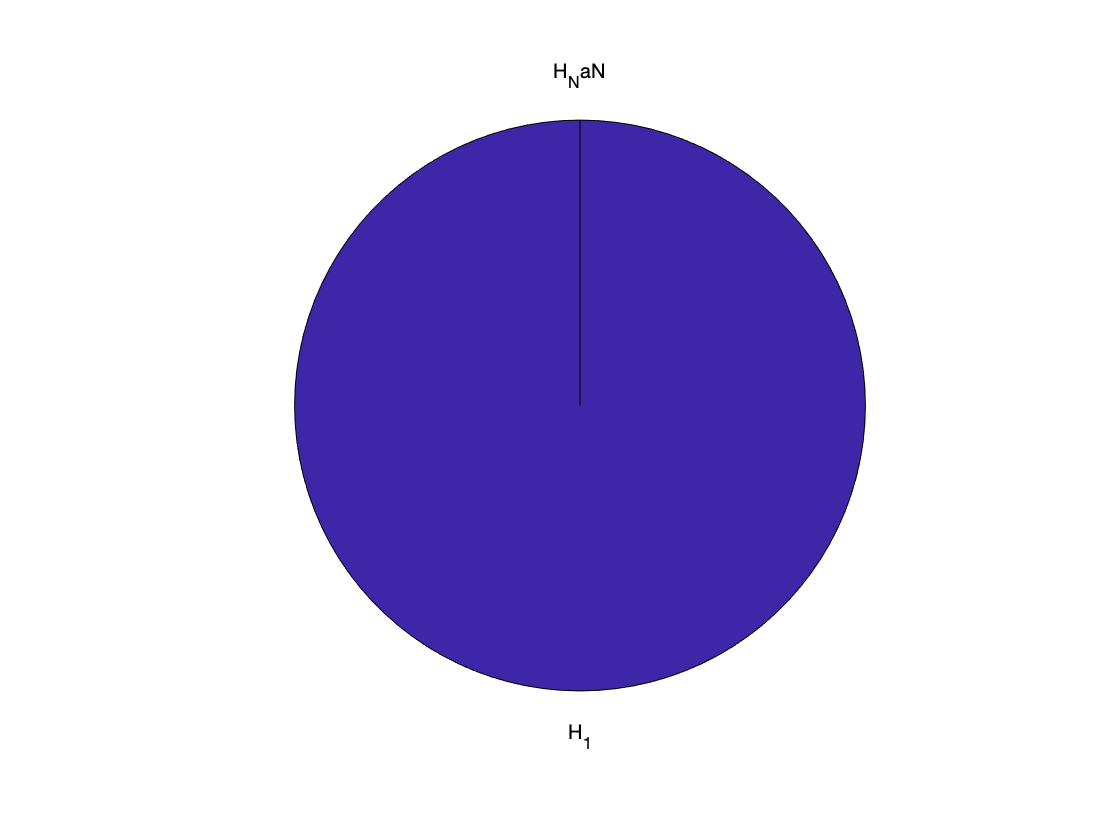

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Solving Instance Set with LPT
solvedInstances_LPT=LPT.solveInstanceSet(InstanceSet);

%Using plotSolverUsageDistributionMulti with LPT 
LPT.plotSolverUsageDistributionMulti(1,true)

**As expected, the only solver used was H1 which corresponds to LPT**

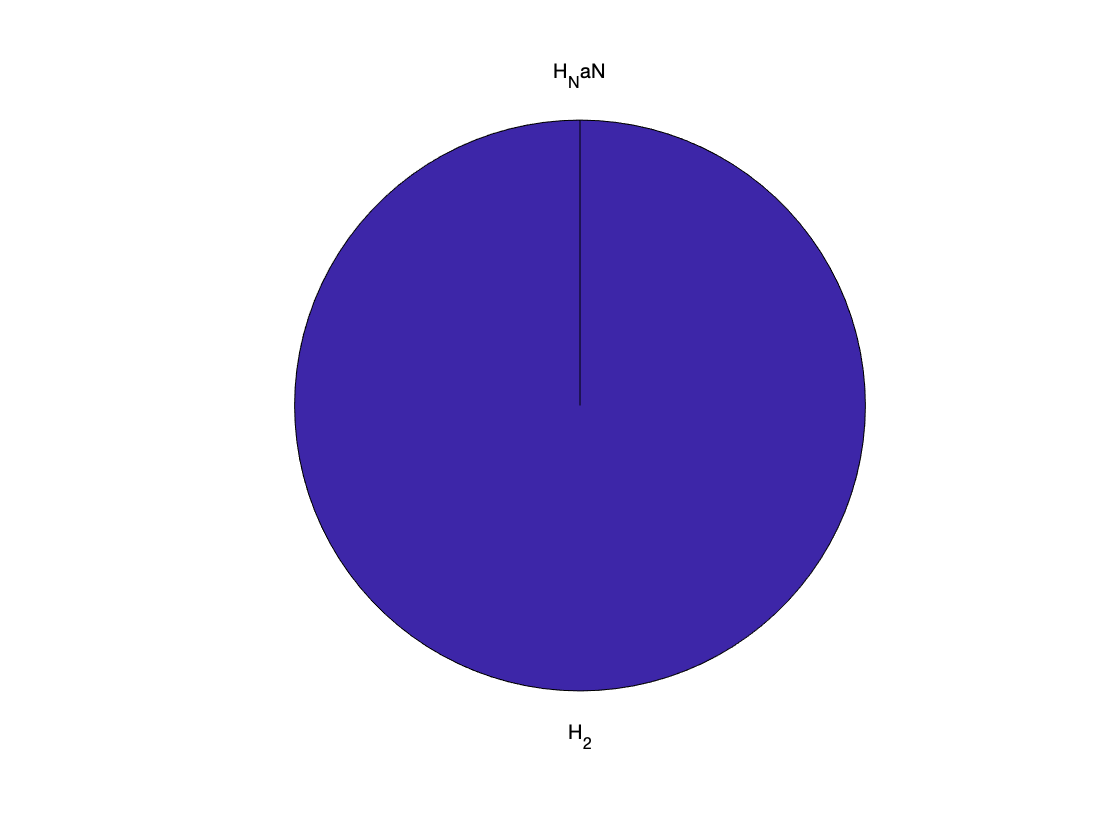

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Solving Instance Set with SPT to confirm that now the used heuristic is H2
solvedInstances_SPT=SPT.solveInstanceSet(InstanceSet);

%Using plotSolverUsageDistributionMulti with SPT 
SPT.plotSolverUsageDistributionMulti(1,true)

**As expeted now the solver changed to H2**

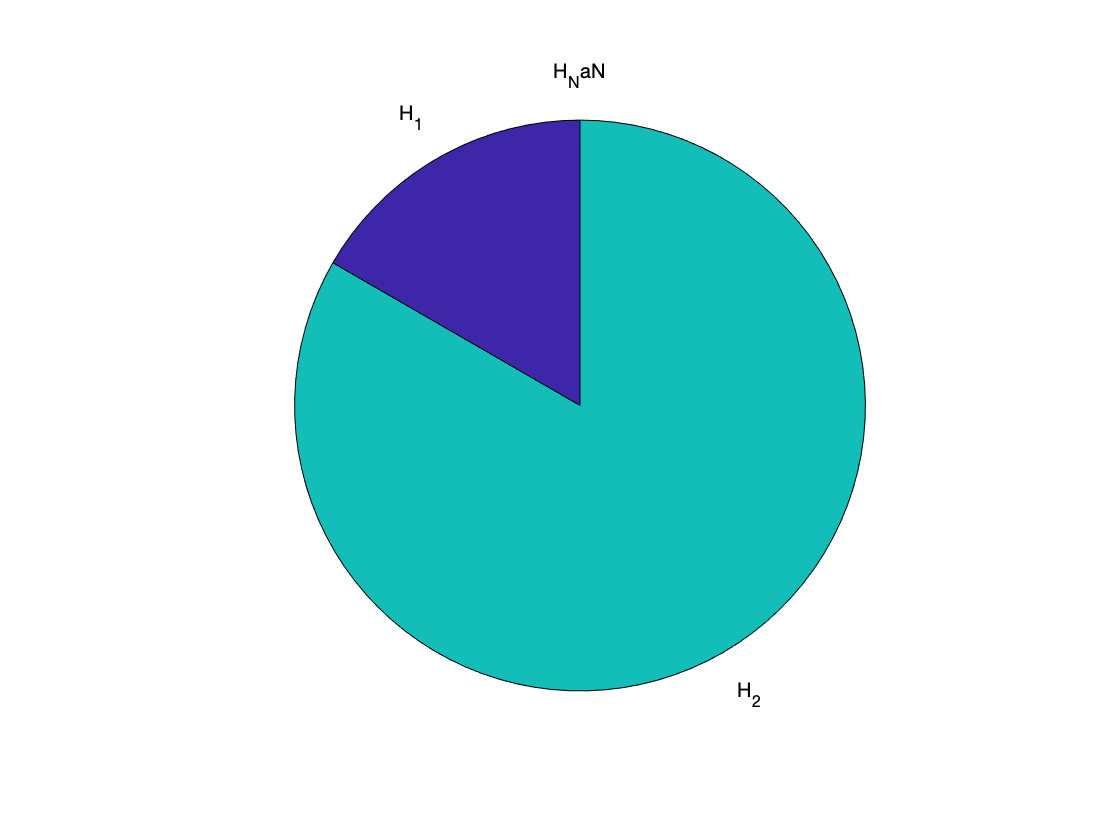

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Solving Instance Set with HH1
solvedInstances_HH1=FM_HH1.solveInstanceSet(InstanceSet);

%Using plotSolverUsageDistributionMulti with HH1 
FM_HH1.plotSolverUsageDistributionMulti(1,true)

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Using plotSolverUsageDistributionMulti with HH1 
FM_HH1.plotSolverUsageDistributionMulti(2,true)

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%Using plotSolverUsageDistributionMulti with HH1 
FM_HH1.plotSolverUsageDistributionMulti(3,true)

ans =   Axes with properties:

             XLim: [-1.2000 1.2000]
             YLim: [-1.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%Using plotSolverUsageDistributionMulti with HH1 
FM_HH1.plotSolverUsageDistributionMulti(4,true)

**The plots of instances I1 and I4 are very similar, same case with instances I2 and I3. Now let's review the HH1 model to check if it makes sense: **

FM_HH1.value

ans =     0.1000    2.0000
    0.2000    1.0000


**It looks strange, for the model, it would seem like LPT would be used more, but let's see if the next visualization methods help us understand what's happening here. **

## **PlotSolverUsage**

**The method is similar to the previous one, but it gives us information about what heuristic was used in what step towards the solution.**

**This method does not needs a flag and does not support using single heuristics**

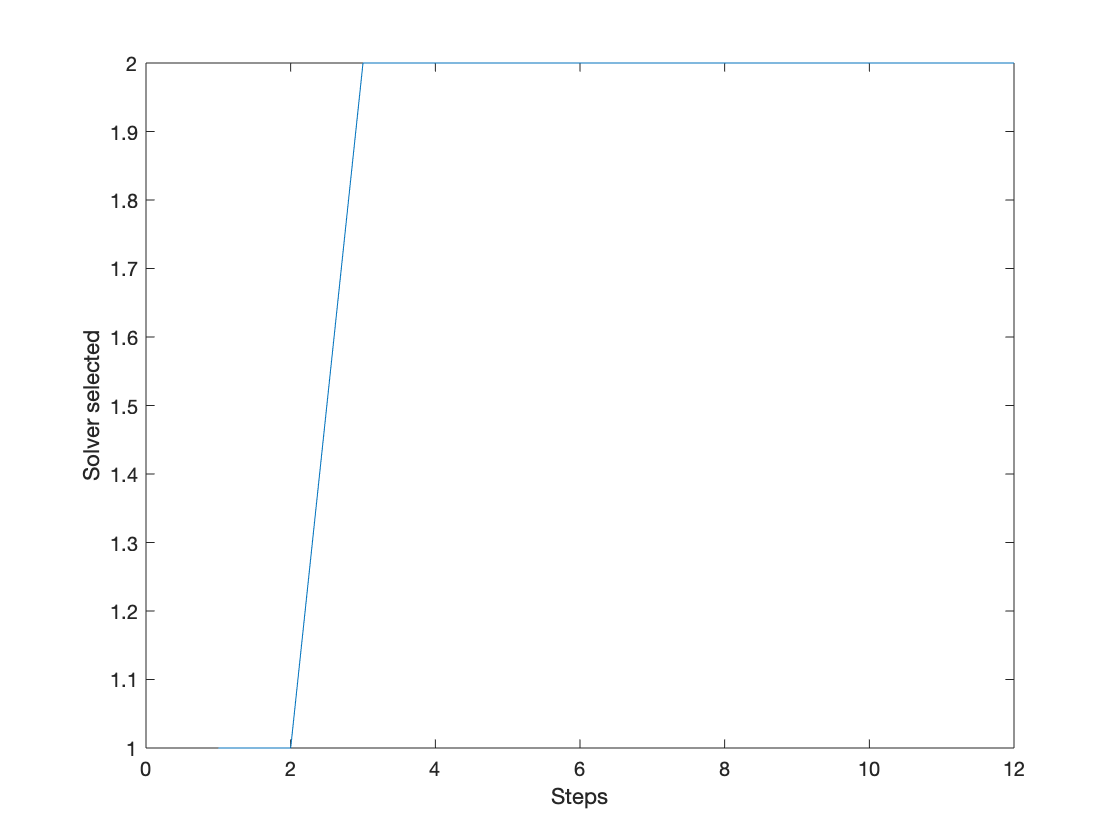

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Let's visualize the four instances
FM_HH1.plotSolverUsage(1) 

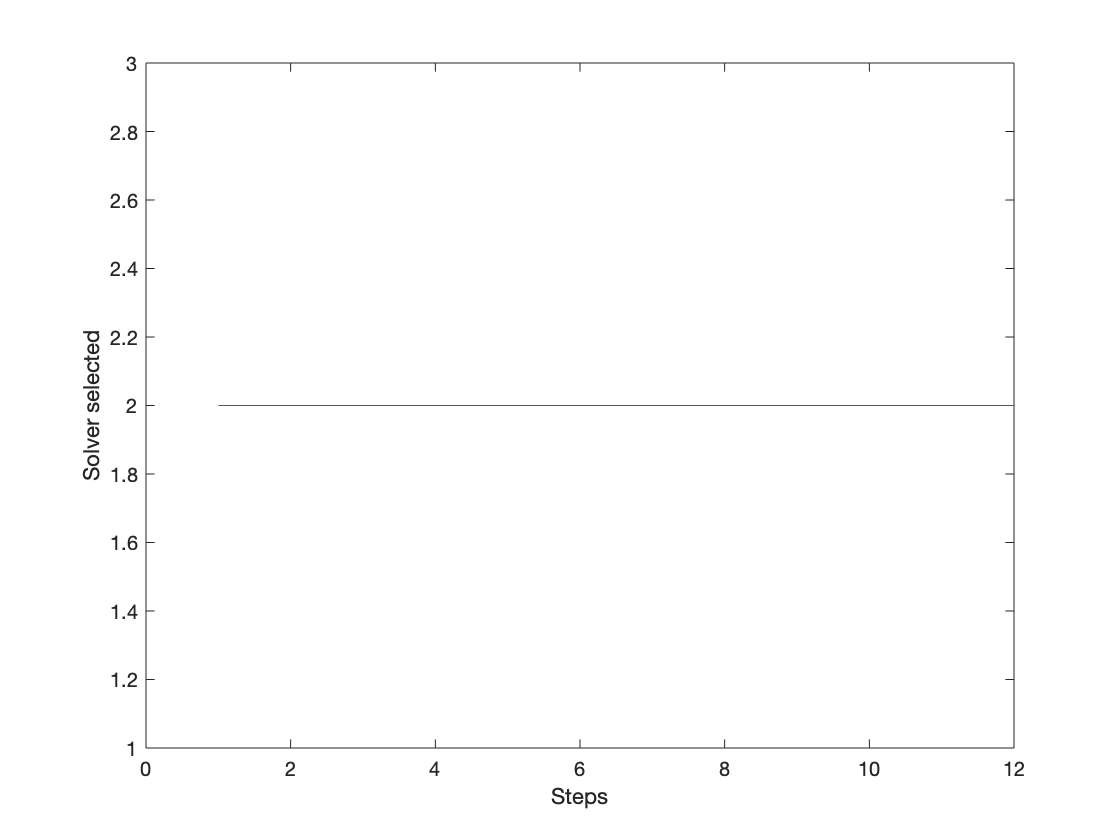

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsage(2) 

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsage(3) 

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsage(4)

**The information is coherent with the previous visualization method becaus I1 is similar to I4, and I2 is similar to I3. **

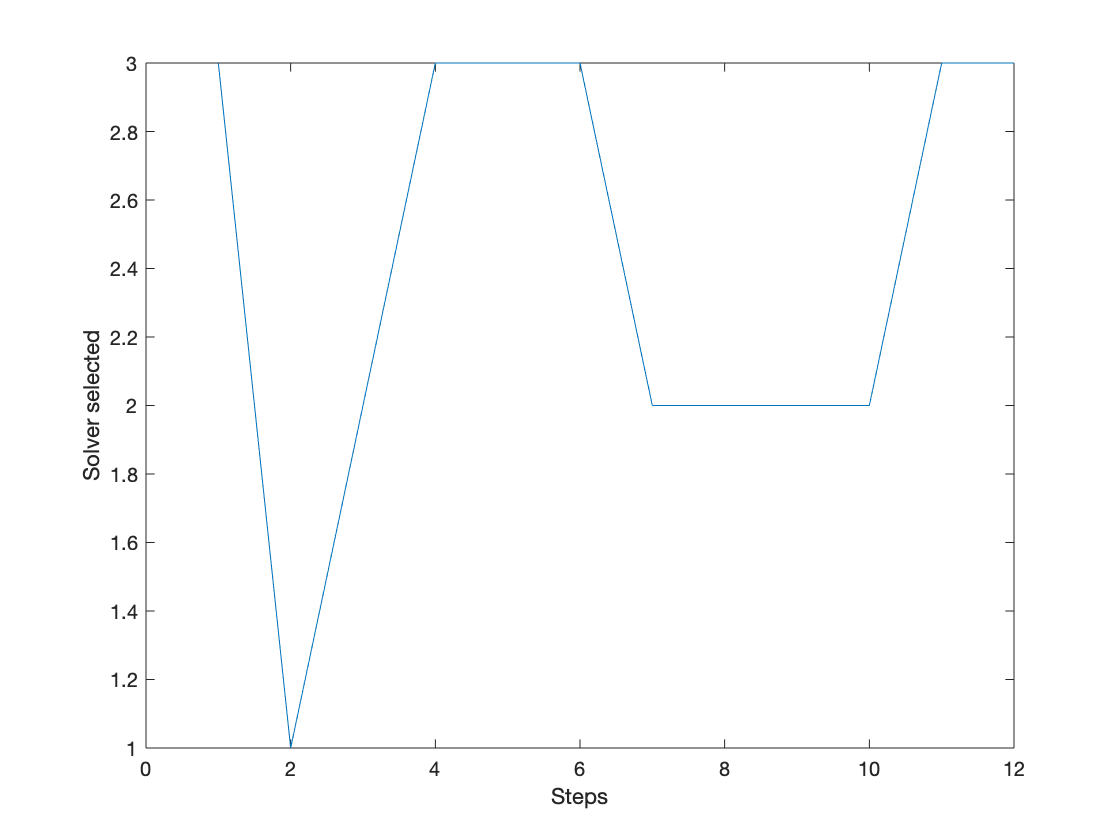

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Let's try some visualization with a SHH 

%solving instance set with SHH1
solvedInstances_SHH1=FM_SHH1.solveInstanceSet(InstanceSet);

%Let's use plotSolverUsage 
FM_SHH1.plotSolverUsage(1)

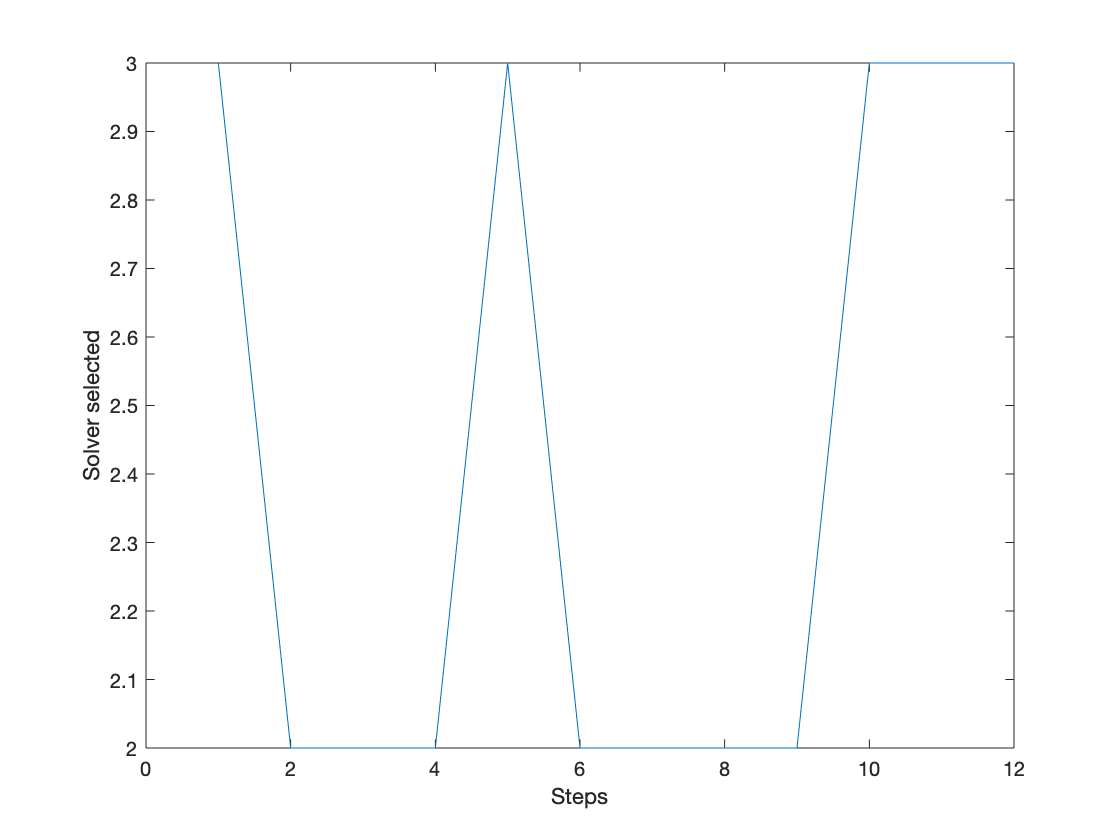

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [2 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsage(2)

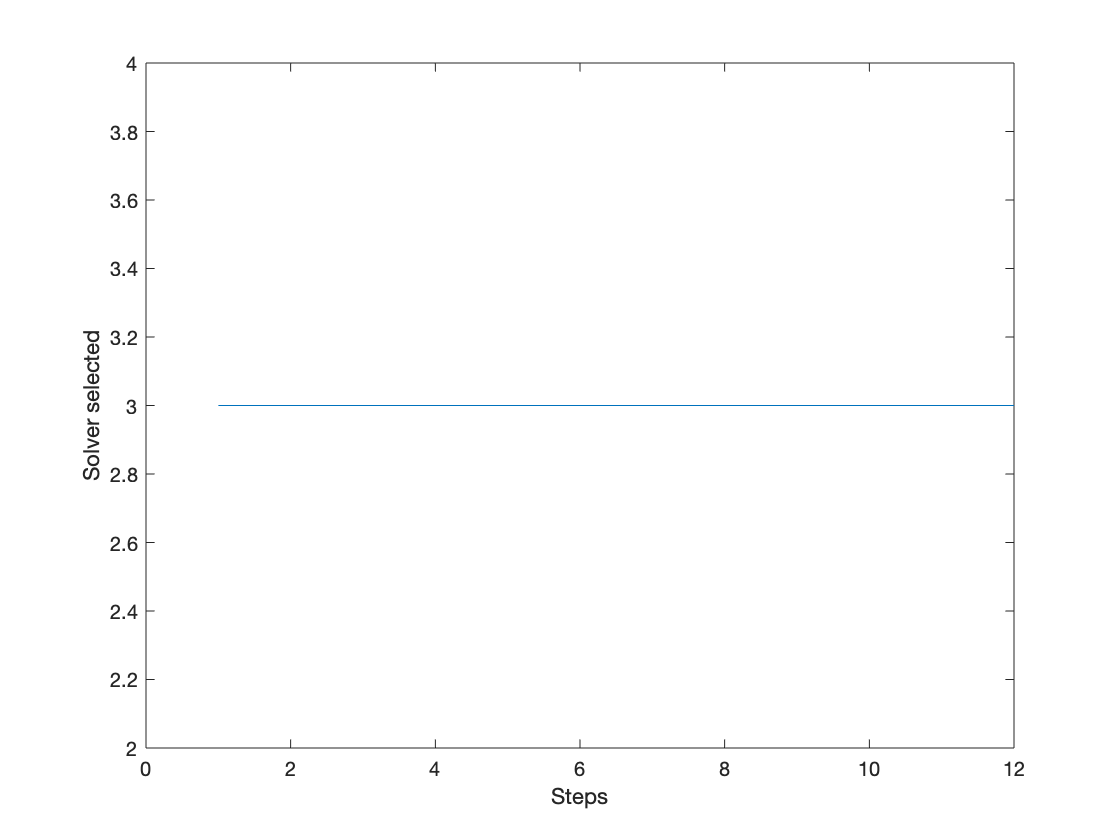

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [2 4]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsage(3)

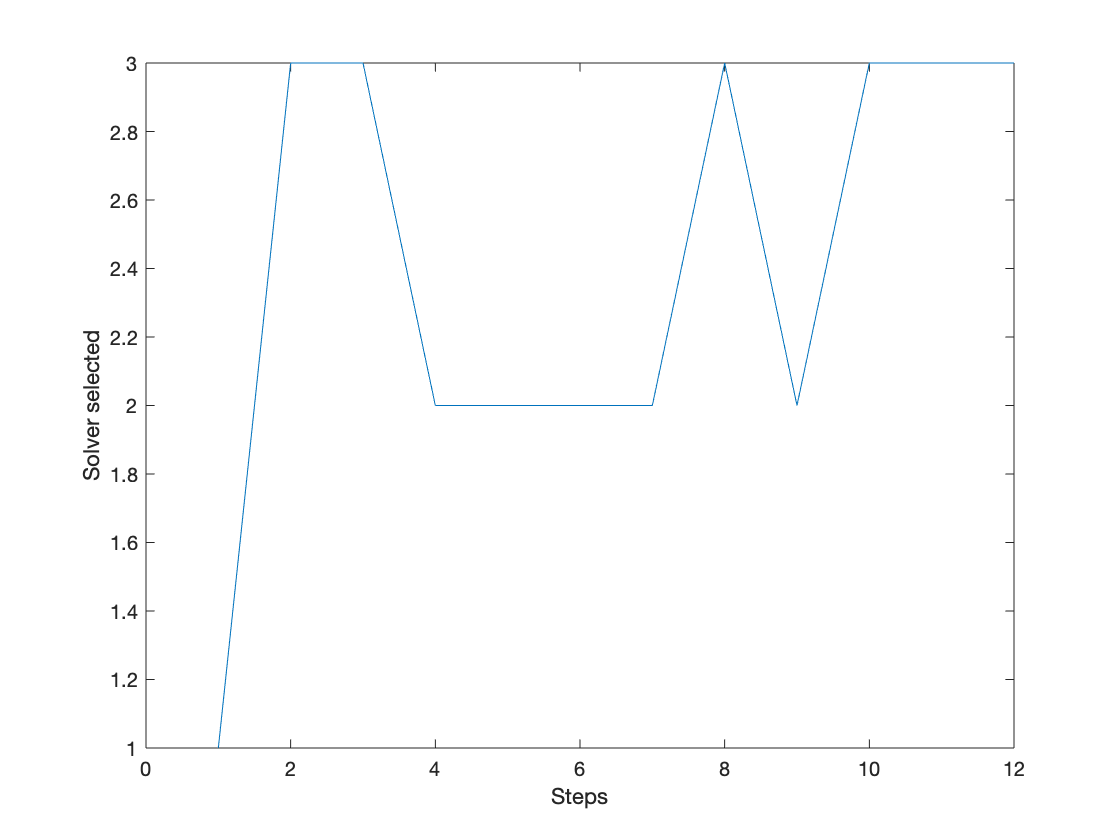

ans =   Axes with properties:

             XLim: [0 12]
             YLim: [1 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsage(4)

**This methods also works with a SHH, and as expected the solutions (except for I3) have more variability. **

## PlotSolverUsageDistribution

This method is similar to PlotSolverUsageDistributionMulti but with the difference that instead of a pie chart, it displays an histogram. This also is not compatible with single heuristic methods (created as single-rule HHs)

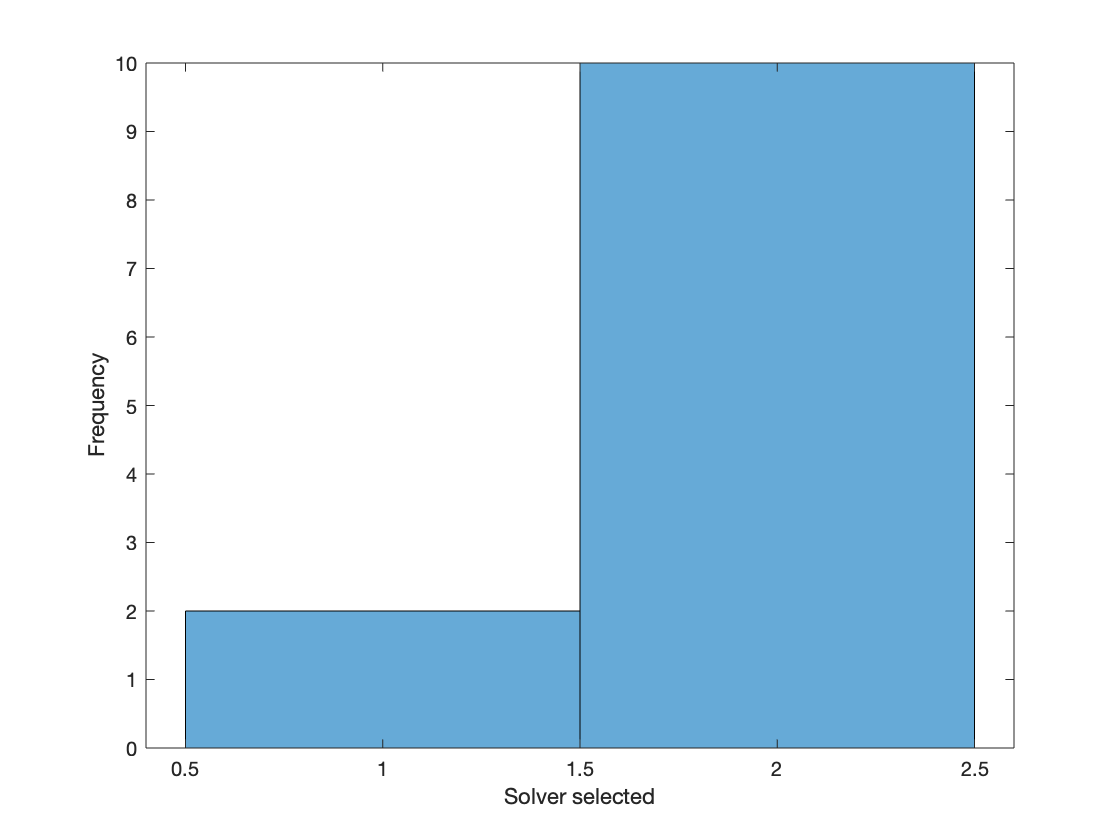

ans =   Axes with properties:

             XLim: [0.4000 2.6000]
             YLim: [0 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Testing HH1
FM_HH1.plotSolverUsageDistribution(1) %first instance

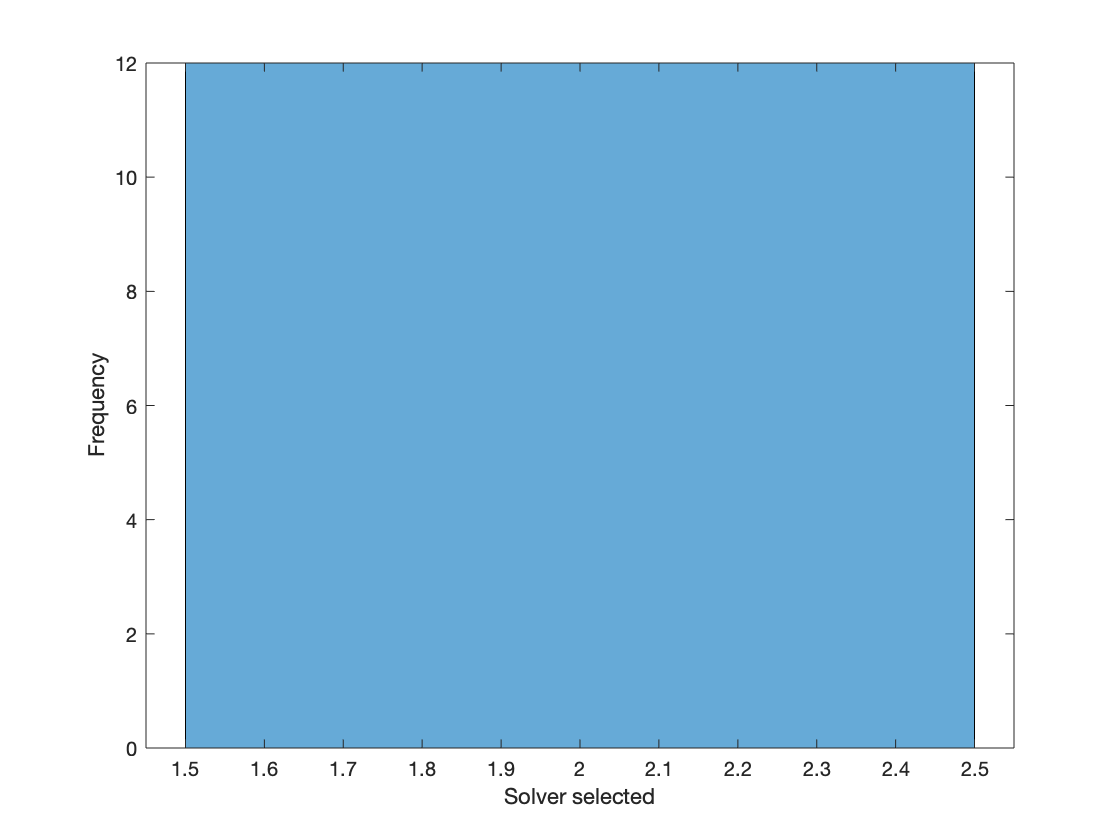

ans =   Axes with properties:

             XLim: [1.4500 2.5500]
             YLim: [0 12]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsageDistribution(2)

ans =   Axes with properties:

             XLim: [1.4500 2.5500]
             YLim: [0 12]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsageDistribution(3)

ans =   Axes with properties:

             XLim: [0.4000 2.6000]
             YLim: [0 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolverUsageDistribution(4)

**It is coherent with previous methods information. Now let's try with an SHH:**

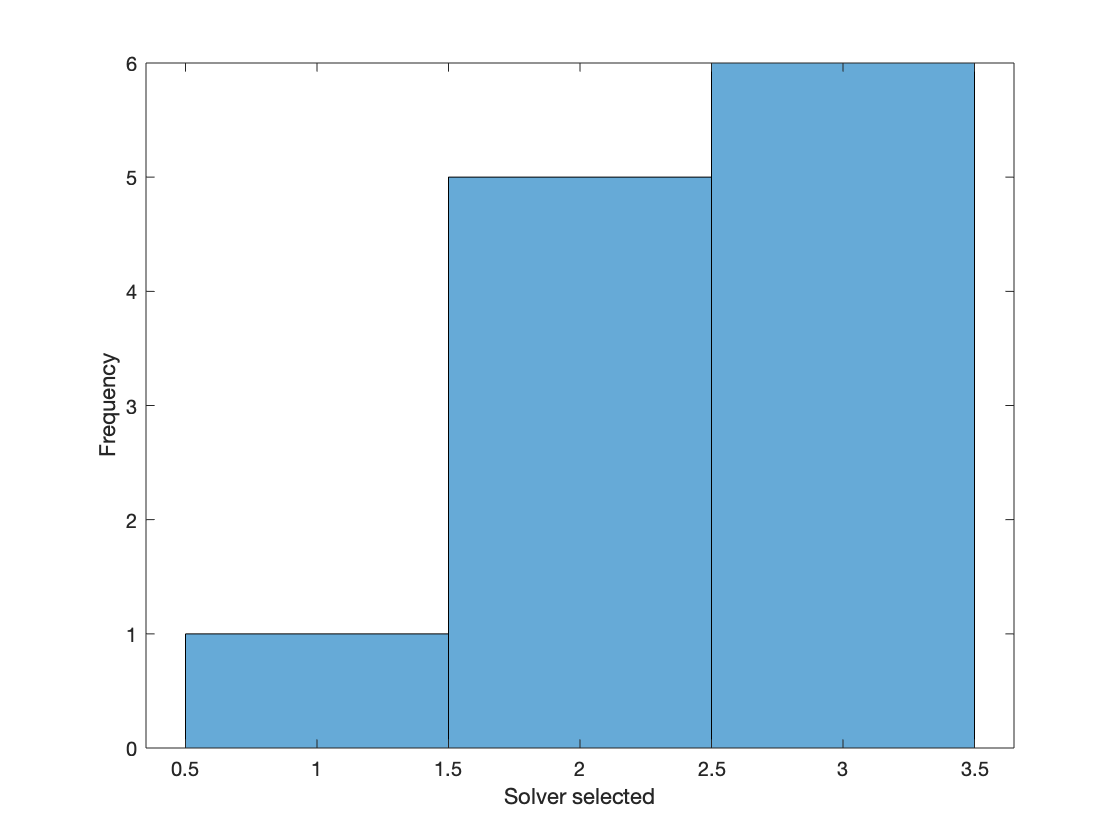

ans =   Axes with properties:

             XLim: [0.3500 3.6500]
             YLim: [0 6]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsageDistribution(1)

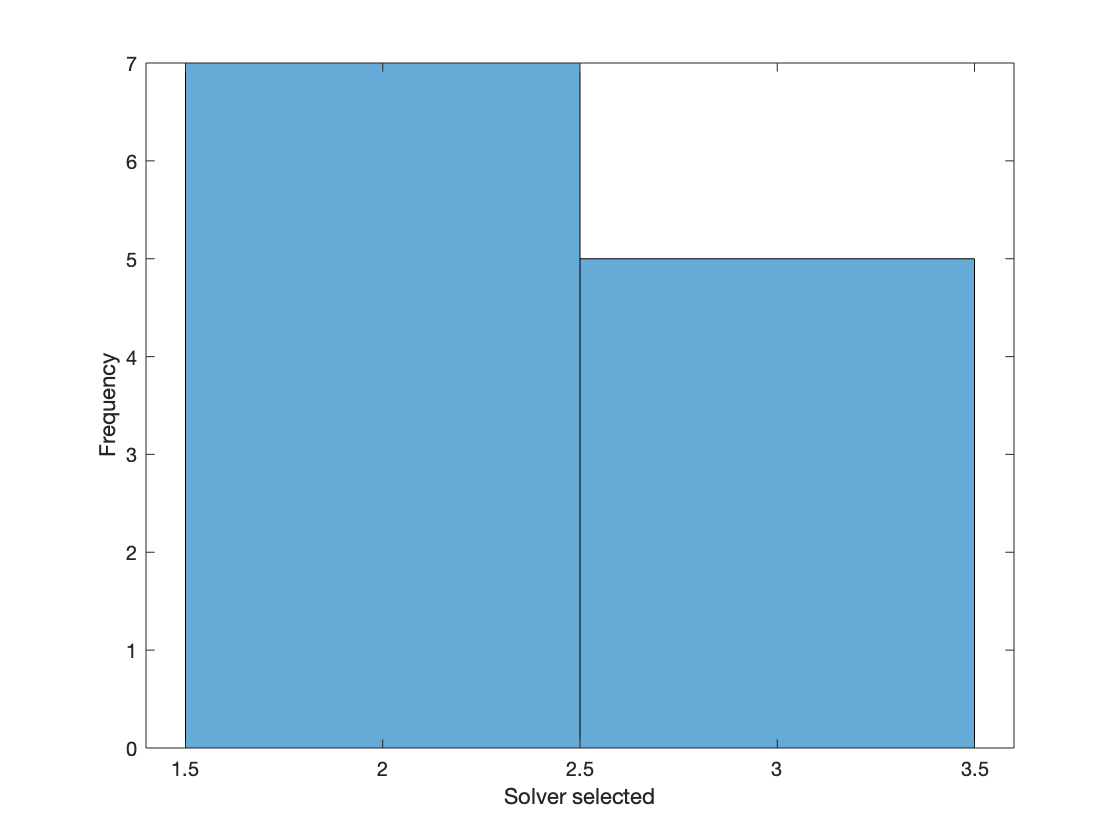

ans =   Axes with properties:

             XLim: [1.4000 3.6000]
             YLim: [0 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsageDistribution(2)

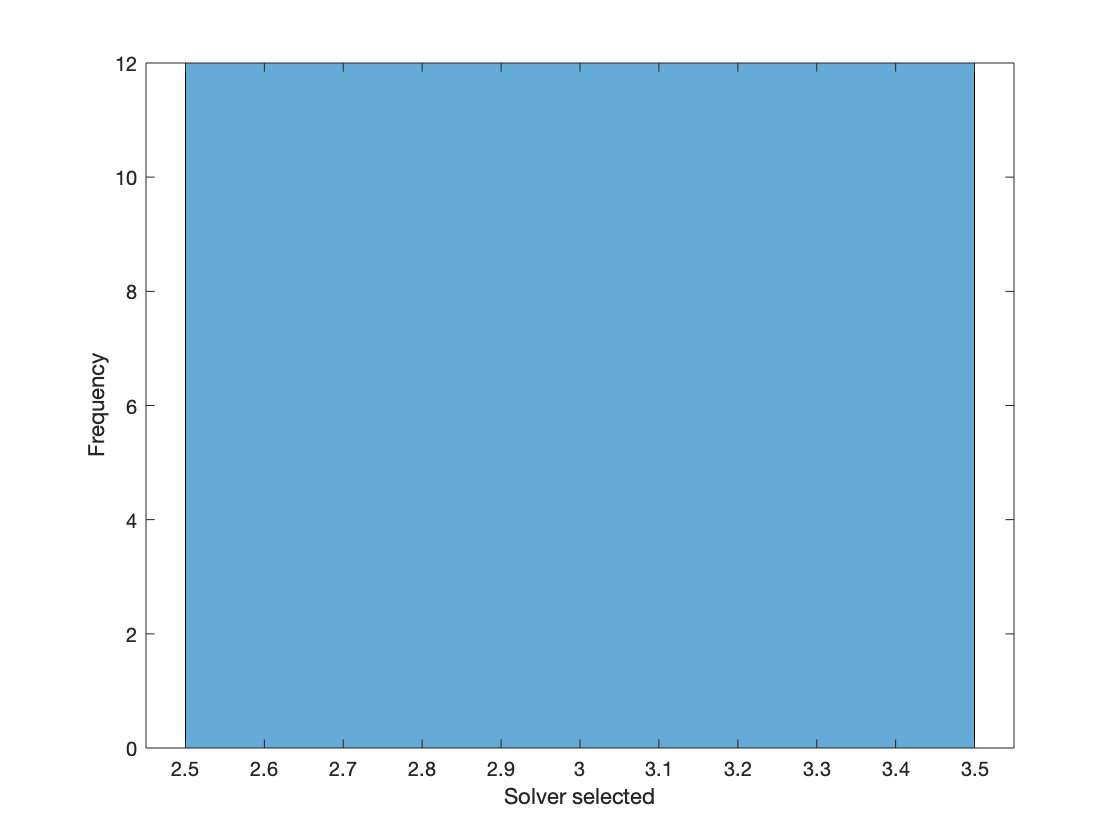

ans =   Axes with properties:

             XLim: [2.4500 3.5500]
             YLim: [0 12]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsageDistribution(3)

ans =   Axes with properties:

             XLim: [0.3500 3.6500]
             YLim: [0 6]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolverUsageDistribution(4)

## PlotSolutionEvolution

This method shows us how the makespan is changing in every step, that is, it shows the makespan at a certain time. 

The first argument should be the selected Instance to analyze

The method does not support single heuristics

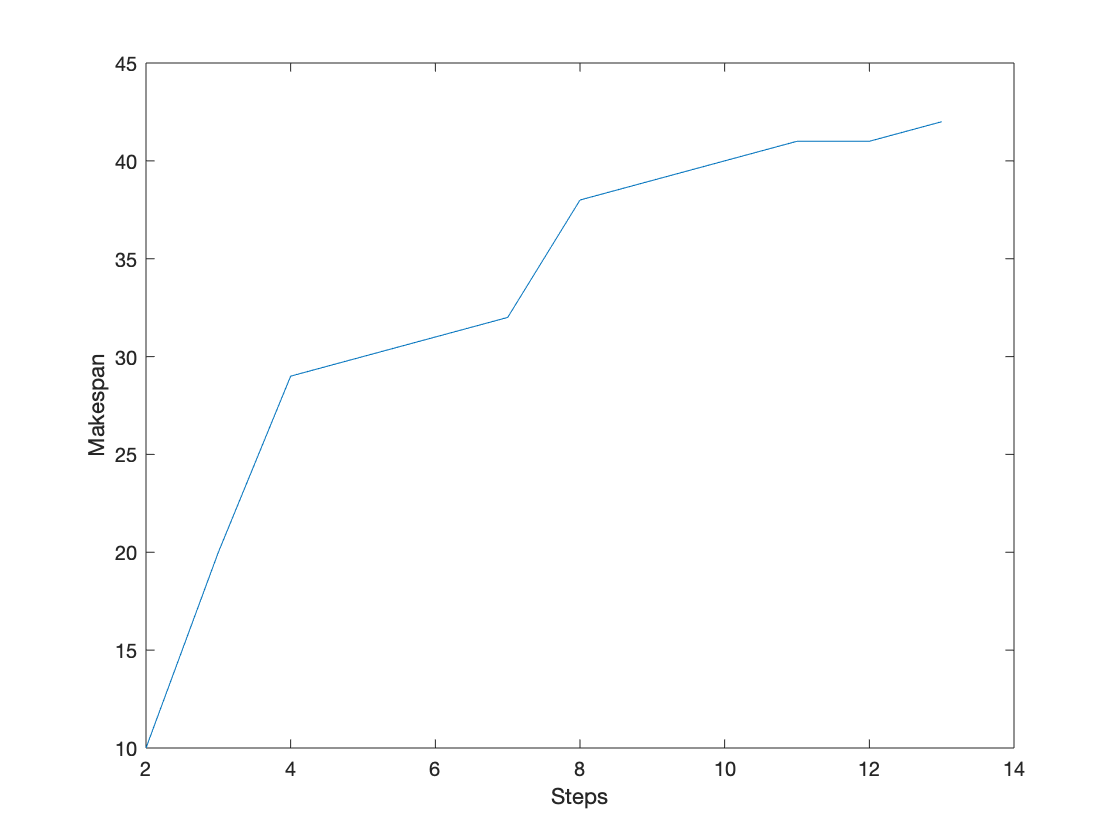

ans =   Axes with properties:

             XLim: [2 14]
             YLim: [10 45]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%testing HH1
FM_HH1.plotSolutionEvolution(1)

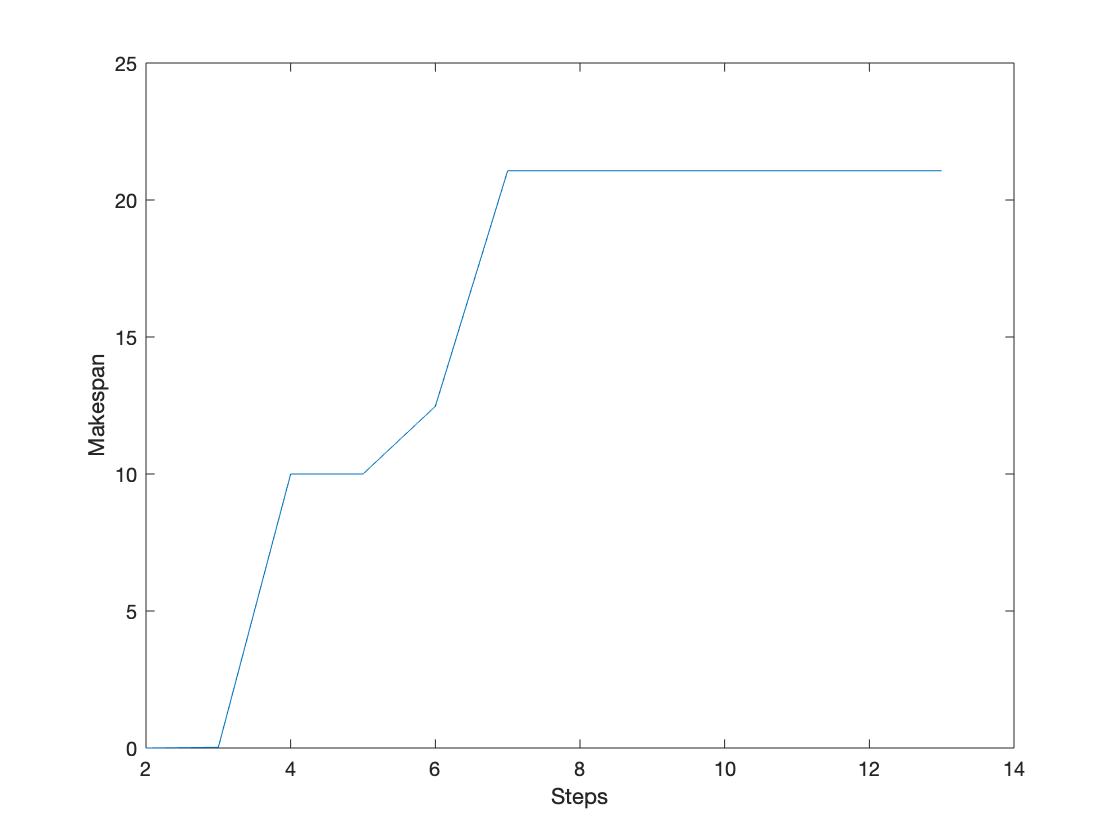

ans =   Axes with properties:

             XLim: [2 14]
             YLim: [0 25]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolutionEvolution(2)

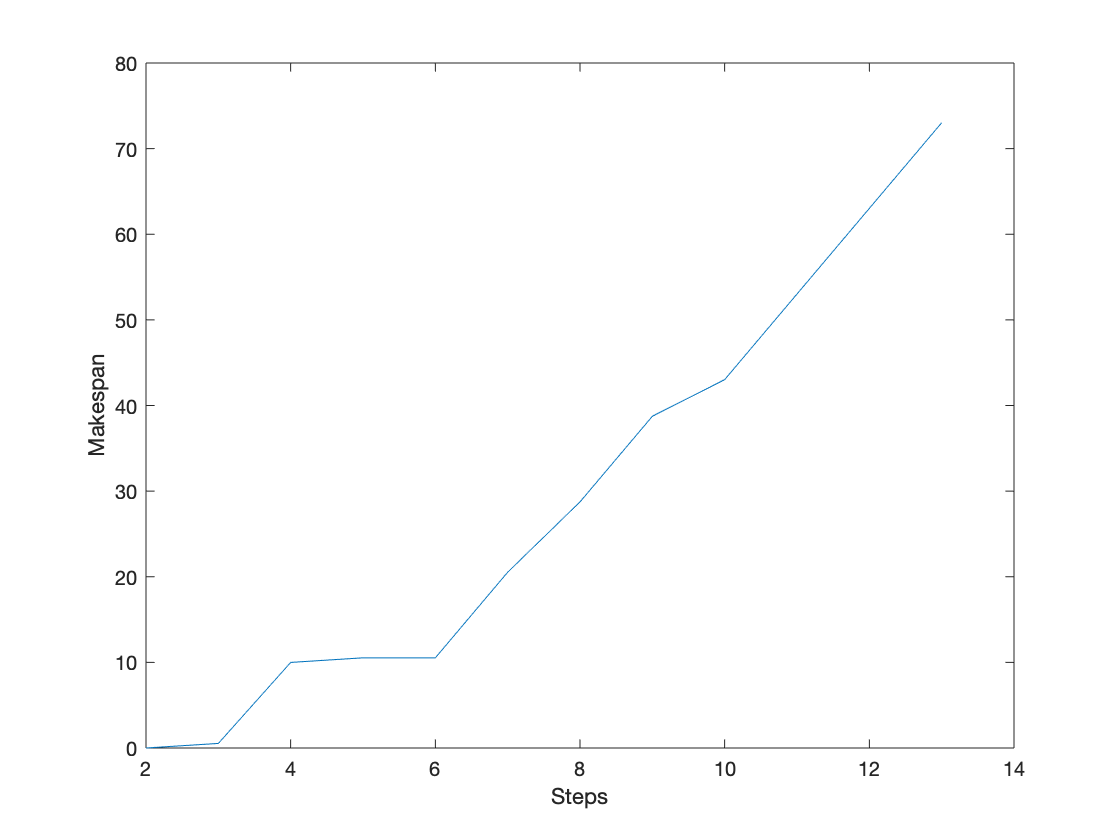

ans =   Axes with properties:

             XLim: [2 14]
             YLim: [0 80]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolutionEvolution(3)

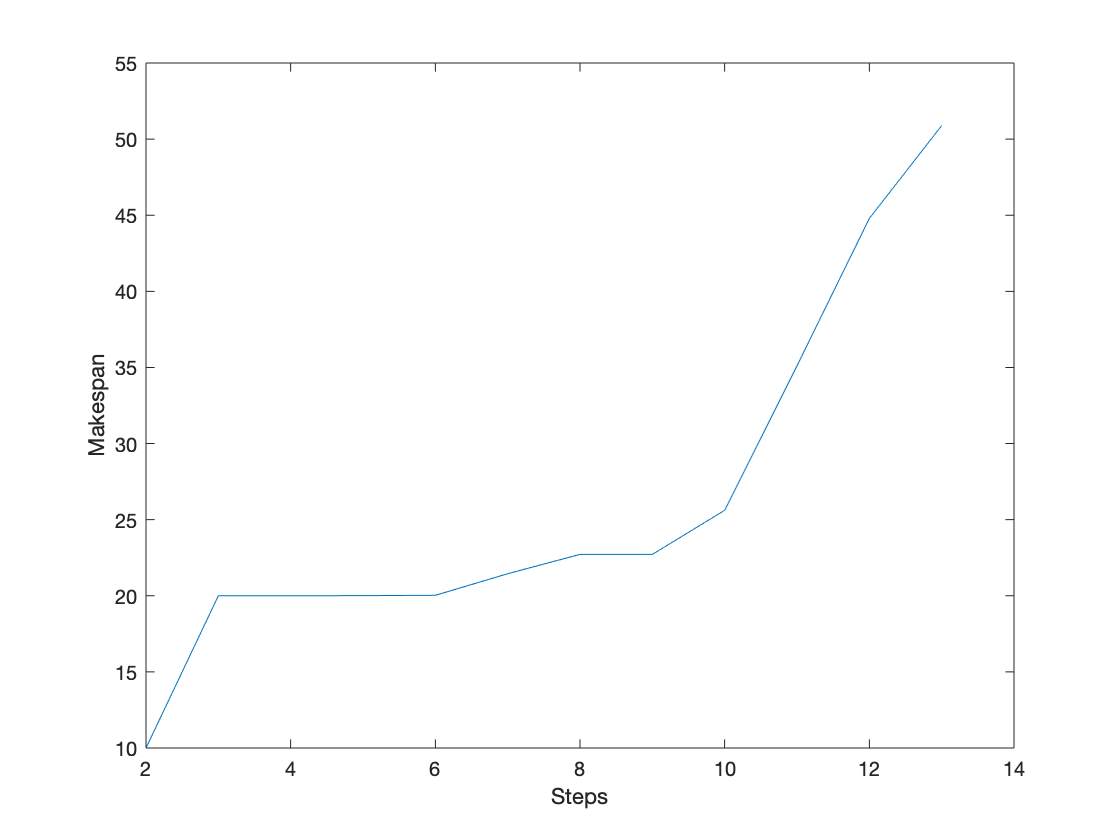

ans =   Axes with properties:

             XLim: [2 14]
             YLim: [10 55]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_HH1.plotSolutionEvolution(4)

**As expected all plots are diffrent. Now let's visualize SHH1:**

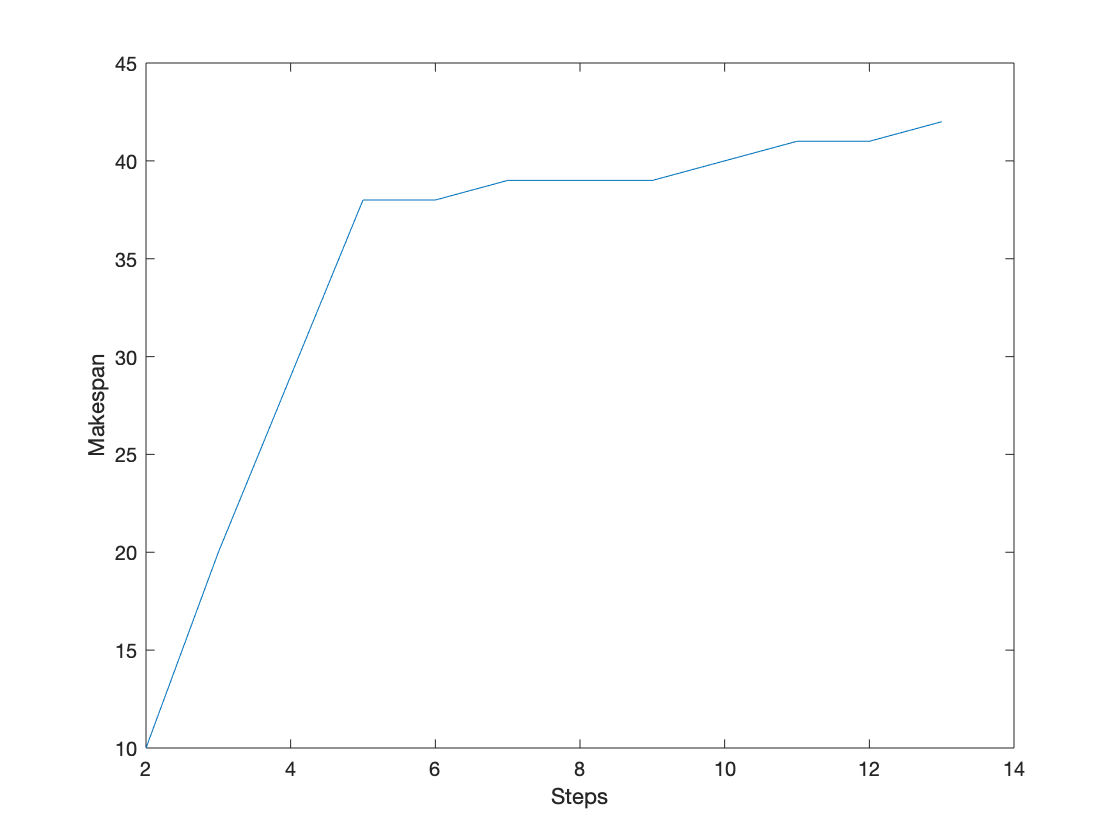

ans =   Axes with properties:

             XLim: [2 14]
             YLim: [10 45]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


FM_SHH1.plotSolutionEvolution(1)

## PlotSolution

This method is to visualize the schedule of a certain instance in a certain time. 

The arguments are:

1: the desired instance 

2: the desired step 

*It does not work if we select the first step. It works with single heuristics or multi.class solvers*

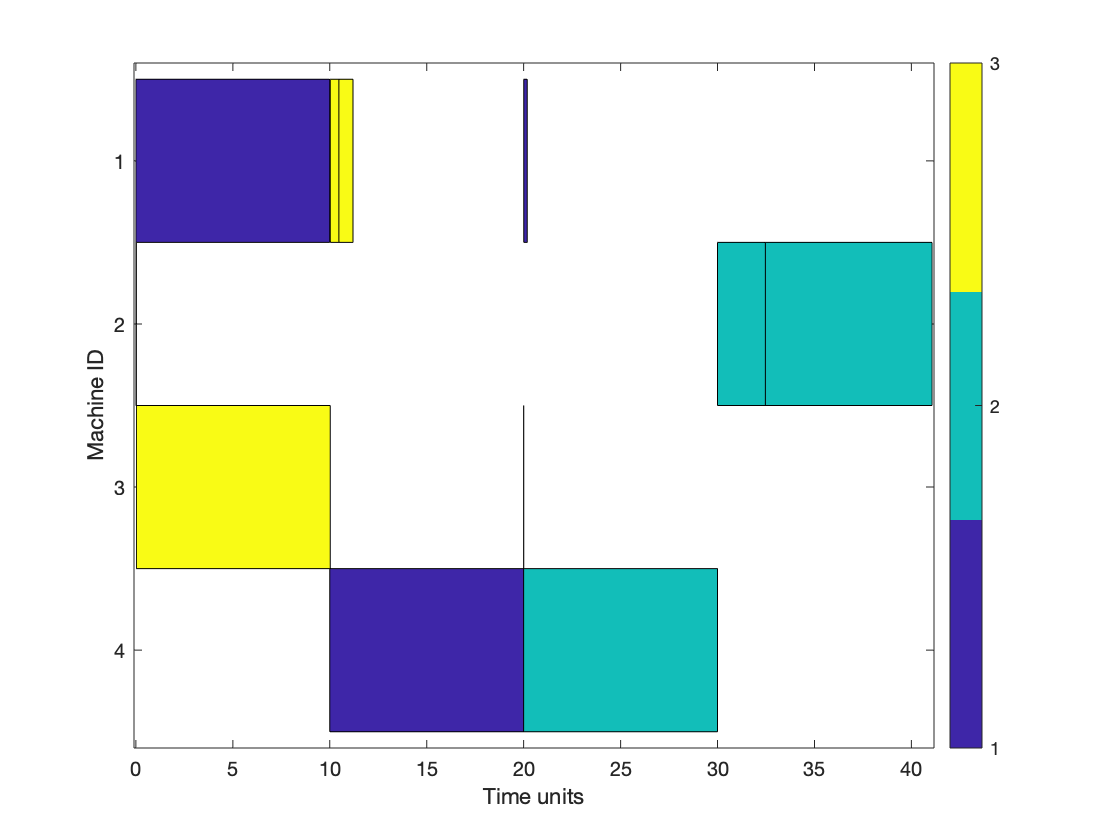

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


LPT.plotSolution(2,'end')

## PlotZones 

Method for plotting a rule-based HH

This method uses the current HH model to plot the regions  where each action is selected. By default, it plots against the first two features of the model and uses a fixed number of points, although behaviour can be altered with optional arguments.

 Optional inputs (default values):

             -\ ---\ points (0:0.01:1) - Vector with the points that will be evaluated (per dimension)

             -\ ---\ isEuclidean (true) - Flag indicating if Euclidean distance will be used

             -\ ---\ selectedFeatures (1:2) - Vector with two elements containing the IDs of the features (columns) to use when plotting

             -\ ---\ doRules (false) - Flag indicating if the rules should be plotted as well

     -\ Returns:

        -\ ---\ allAreas - Vector with areas occuppied by each action

The inputs must be inserted in order

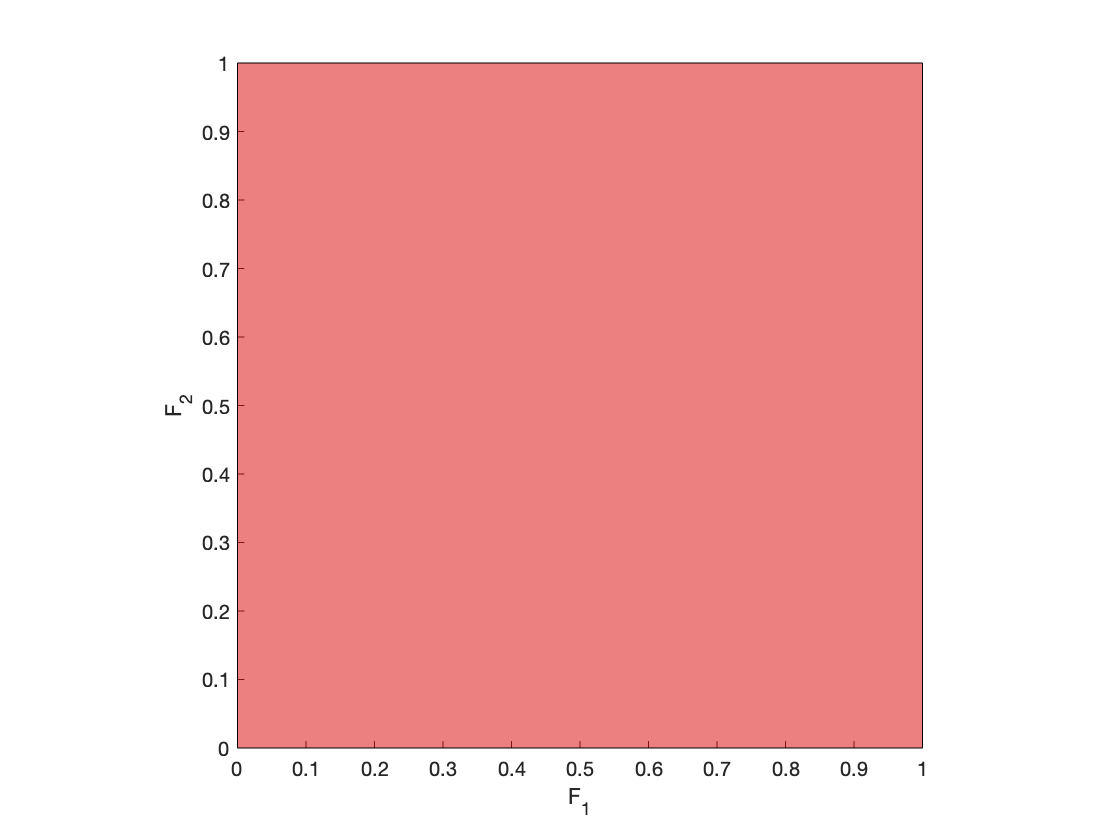

ans = 1.0000

LPT.plotZones()

**As expected, LPT only uses LPT, that is why all is red. Now let's try a HH model: **

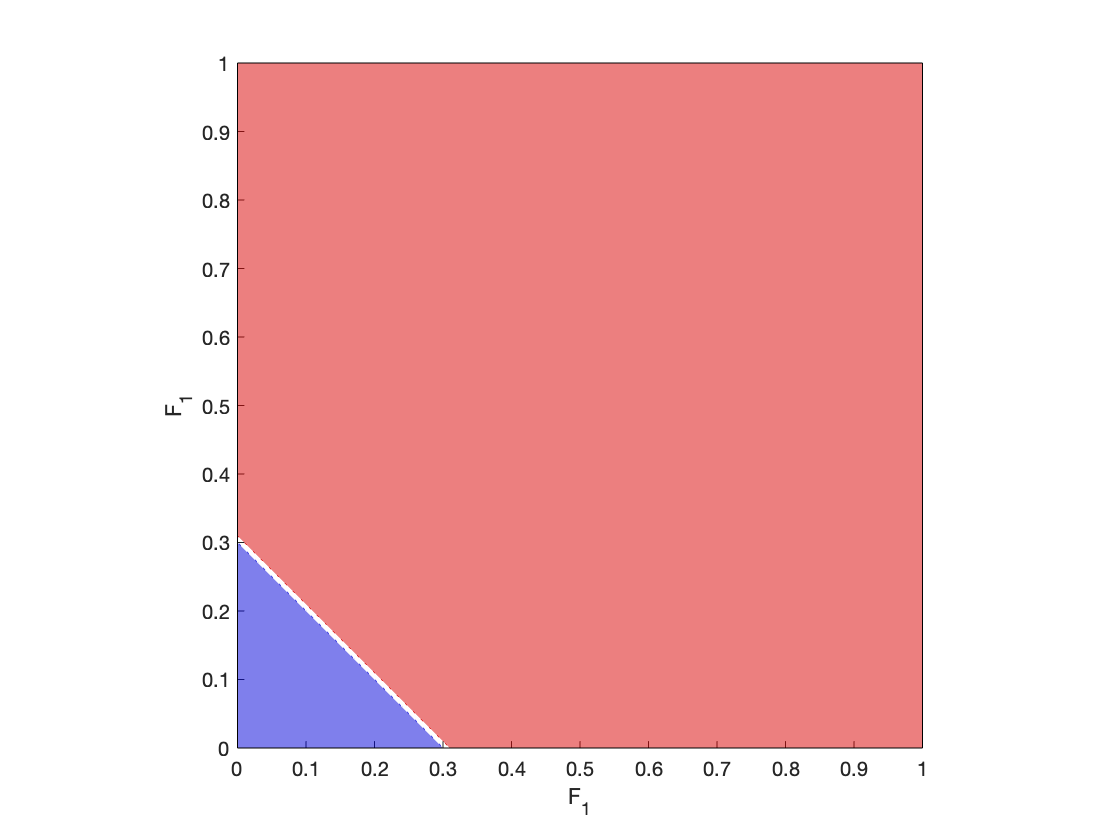

ans =     0.9519    0.0450


FM_HH1.plotZones()

**The method chooses to plot against the same feature because the model only uses 1. Now a SHH: **

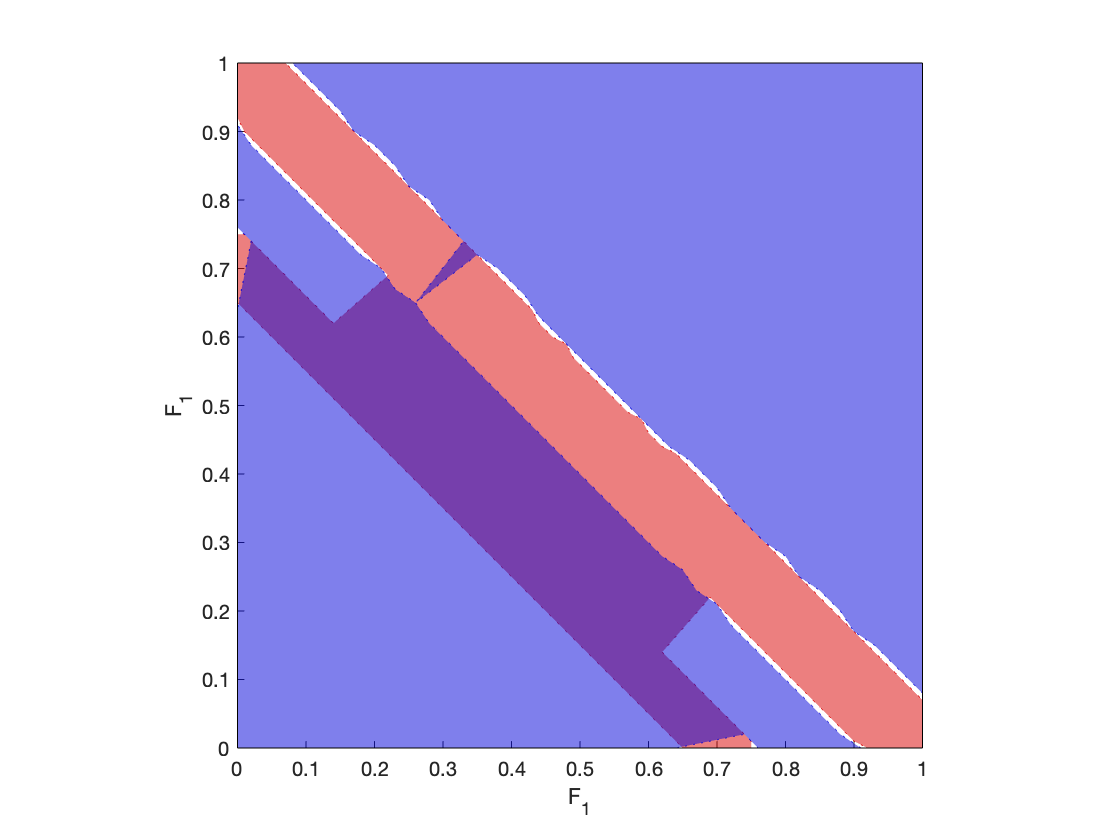

ans =     0.3004    0.8332


FM_SHH1.plotZones()

**This has a more complex model, therefore a more complex plot. Let's see the model: **

FM_SHH1.value

ans =     0.5000    1.0000
    0.3500    1.0000
    0.4100    2.0000
    0.3000    2.0000
    0.5700    2.0000


**Now let's plot the rules and increase the resolution: **

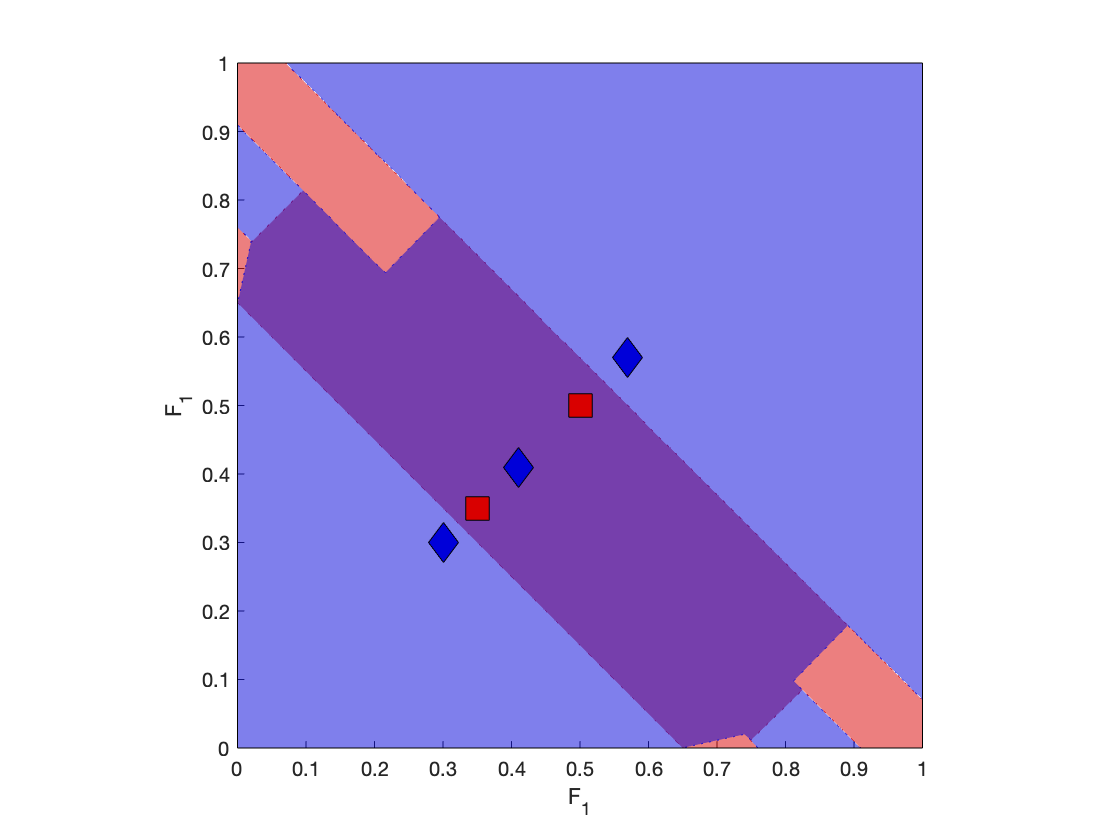

ans =     0.3403    0.9392


FM_SHH1.plotZones(0:0.001:1,1,[1 1],1)

## PlotFeatureMap

This method helps visualizing the evolution of the features. It solves an instance set with the given solver and maps the trajectory that the selected feature(s) follows.

With the following code we can select what two features we want to visualize, the most useful so far is to choose the same feature in both axis so we can track its evolution. If we only want to follow one feature, we need the next flag to be true and then the desired instance from the given set. 

For example:

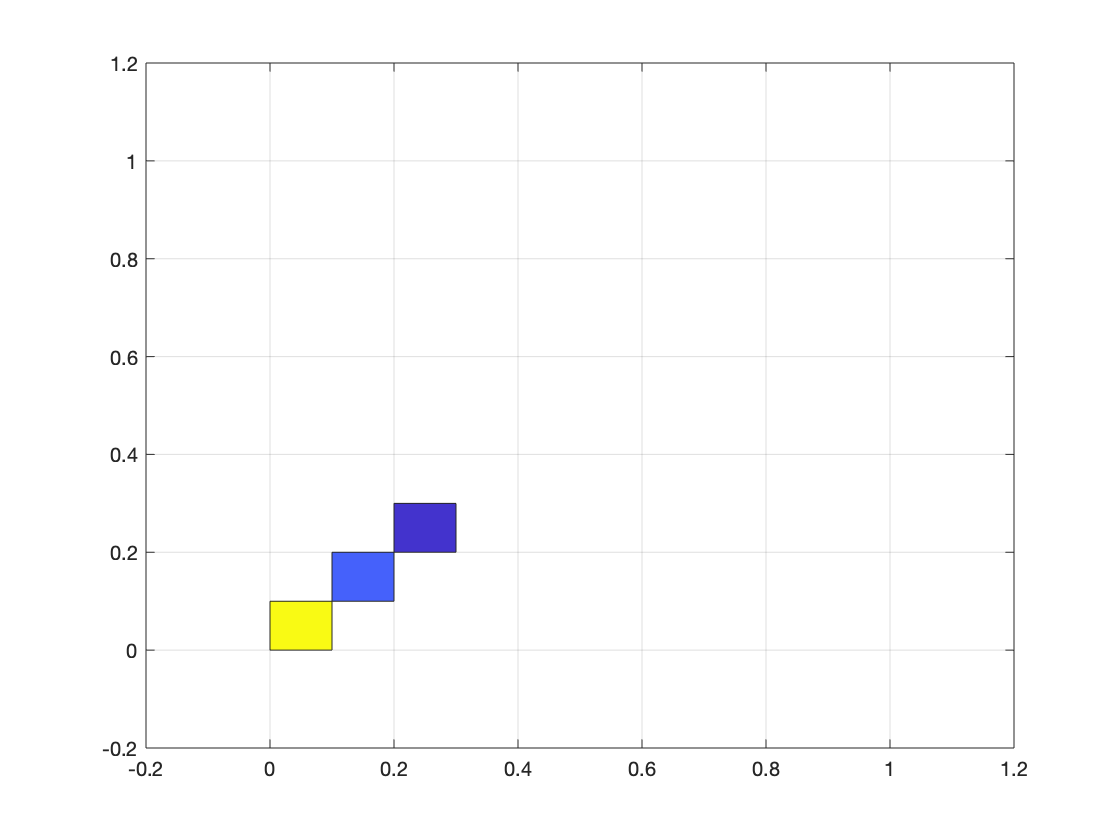

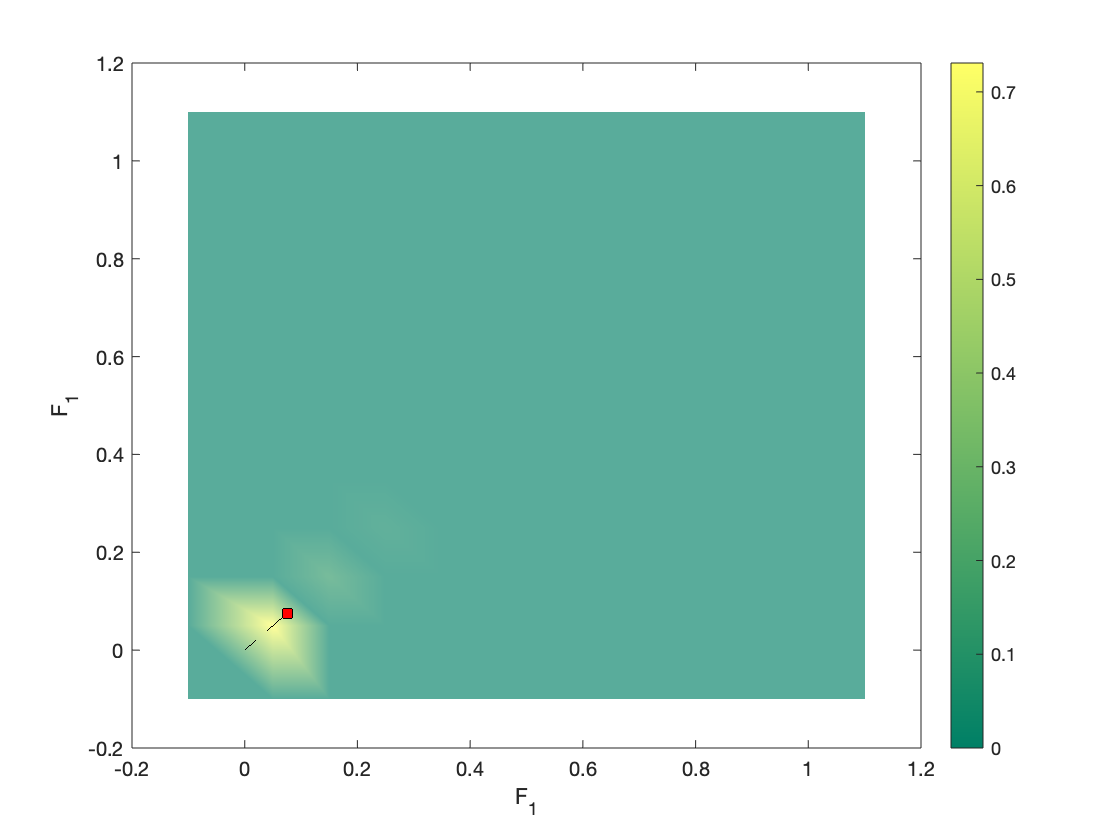

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


LPT.plotFeatureMap(InstanceSet,"full",struct('features',[1 1]),true,3)

**Let's see if the map corresponds to the values of I3:**

I3.getFeatureVector([1 2 3 4 5])

**It seems that the red square is telling the final value of the first feature for the third instance.**

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


ans =     0.2544    0.3334    0.3767    0.6667    0.3333


ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties
